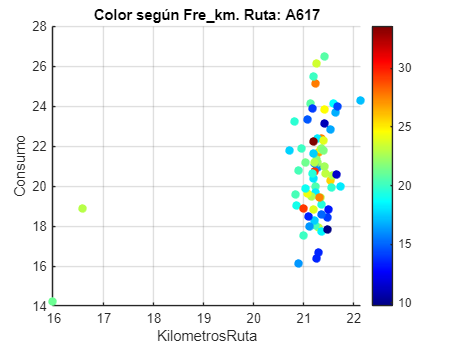

ejeX = 'KilometrosRuta';
ejeY = 'Consumo';
ejeColor = 'Fre_km'; % columna numérica directa
ruta_especifica = "A617";

nombreRutaString = string(Tabla.NombreRuta);

% Filtro para la ruta
idx_ruta = strcmp(strtrim(nombreRutaString), strtrim(ruta_especifica));
idx_x = ~isnan(Tabla.(ejeX));
idx_y = ~isnan(Tabla.(ejeY));
idx_c = ~isnan(Tabla.(ejeColor));

idx = idx_ruta & idx_x & idx_y & idx_c;

X = Tabla.(ejeX)(idx);
Y = Tabla.(ejeY)(idx);
C = Tabla.(ejeColor)(idx);

if isempty(X)
    disp('No hay datos válidos para graficar después de limpiar y filtrar.');
else
    figure;
    scatter(X, Y, 40, C, 'filled');
    colormap('jet');
    colorbar;
    xlabel(ejeX, 'Interpreter', 'none');
    ylabel(ejeY, 'Interpreter', 'none');
    title(['Color según ' ejeColor '. Ruta: ' char(ruta_especifica)], 'Interpreter', 'none');
    grid on;
end